# Quickstart Guide: Dynamics

This guide assumes you already know how to create networks of cells and how to access cell identifiers.

## Template Network

Here we will create the example network that we will use for this guide. It is a two-cell ball and stick model network

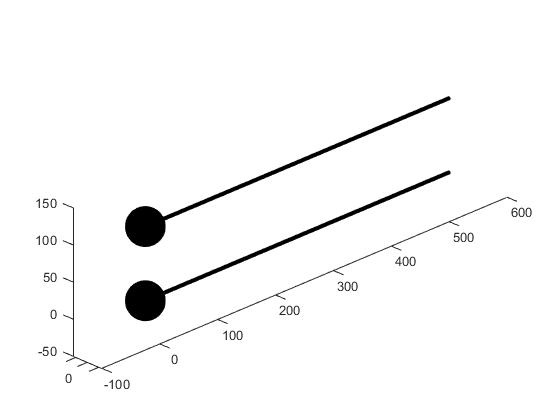

soma = ELFENN.Section('soma', 'radius', 25, ...
    'sectionLength', 50, 'nSeg', 1, 'sectionGeometry', 'S');
axon = ELFENN.Section('axon', 'radius', 2.5, ...
    'sectionLength', 500, 'nSeg', 21);
cell = ELFENN.Cell('cell1');
cell.connectsection(soma, axon, [0,0,0]);
network = ELFENN.Network();
network.addcell(cell, [0,0, 0]);
cell.name = 'cell2';
network.addcell(cell, [0,0, 100]);
network.complete();

plotnetwork(network);
view([-45. 25]);

## Cellular Dynamics

Here we are going to add Hodgkin-Huxley dynamics to our cells in the network. ELFENN comes with 3 mechanisms for dynamcs: Hodgkin-Huxley, Fast-Spiking Interneuron, and Passive dynamics. To create custom dynamics see the next section on custom dynamics.

We'll first create a function handle to the ode function and get the default parameters

handle = @ELFENN.Mechanisms.Cellular.HH.ode;
p = ELFENN.Mechanisms.Cellular.HH.default_parameters;
disp(p)

    ENa: 50
     EK: -77
     EL: -54.3000
    gNa: 120
     gK: 36
     gL: 0.3000
      C: 1



We can see that these are the typical parameters for the Hodgkin-Huxley model GNa, EK, ...

network.setdynamics(p);

Interestingly enough this does not add the dynamics to the model but it sets the model parameters for each segment. ELFENN works on the principle of uniformity across cells, all compartments have the same ODE, certainly they can have different parameters, including removing currents by setting conductances to 0, they all have the same function. While this does have it's pros and cons this is for the moment how ELFENN works.

For example to make passive somas we can edit their properties to remove Sodium and Potassium currents

soma1 = network.getcellbyname('cell1').soma;
soma2 = network.getcellbyname('cell1').soma;

network.sectionsearchbyseg(soma1).dynamicsParameters.gNa = 0;
network.sectionsearchbyseg(soma1).dynamicsParameters.gK = 0;
network.sectionsearchbyseg(soma2).dynamicsParameters.gNa = 0;
network.sectionsearchbyseg(soma2).dynamicsParameters.gK = 0;

The method *sectionsearchbyseg* is new. It access the parent section of a segment by ID. This is important since the parameters are stored at the section level. If one segment of a section was supposed to have different parameters, the section should be broken at that point into multiple sections.

We won't see how to add the dynamics until the next guide on the "Solver".

## Creating Custom Dynamics

Neural dynamics are functions which take 3 inputs: time, state, and a struct of parameters. We show an example here

type("ELFENN/Mechanisms/Cellular/HH/ode")


function dY = ode(~, y, p)
    
    am = @(v) 0.1 * (v + 40) ./ (1 - exp(-0.1*(v + 40)));
    bm = @(v) 4 * exp(-0.0555556*(v + 65));
    
    ah = @(v) 0.07 * exp(-0.05*(v + 65));
    bh = @(v) 1 ./ (1 + exp(0.1*(-v - 35)));
    
    an = @(v) 0.01 * (v + 55) ./ (1 - exp(-0.1*(v + 55)));
    bn = @(v) 0.125 * exp(-0.0125*(v + 65));
    
    dY = zeros(size(y));
    Vm = y(1:4:end);
    m = y(2:4:end);
    h = y(3:4:end);
    n = y(4:4:end);
    
    membraneCurrent = (-m.^3 .* h .* p.gNa .* (Vm - p.ENa) - ...
        n.^4 .* p.gK .* (Vm - p.EK) - p.gL .* (Vm - p.EL));
    
    
    dY(1:4:end) = membraneCurrent / p.C;
    dY(2:4:end) = (am(Vm) .* (1 - m) - bm(Vm) .* m);
    dY(3:4:end) = (ah(Vm) .* (1 - h) - bh(Vm) .* h);
    dY(4:4:end) = (an(Vm) .* (1 - n) - bn(Vm) .* n);
end


We can see it takes 3 inputs

Time: the current time

y: the state of the system, note that here there are no extracellular potential - this function could be solved without ELFENN. When writing custom functions the only requirement is that Vm is the first variable, and that the variables are intertwined. I.e. for 3 cells with variables Vm, m, n - therefore the variables are (in order)  Vm1, m1, n1, Vm2, m2, n2, and Vm3, m3, n3. This can be seen where the state variables are extracted with jumps of 4 (there are 4 variables).

p: a struct of parameters for the dynamics such as gNa, or EK. This is completely up the use what to define for custom dynamics. The only requirement for ELFENN is the the field 'C' which defines the capacitance.

An example of the hodgkin huxley parameters are shown

disp(ELFENN.Mechanisms.Cellular.HH.default_parameters);

    ENa: 50
     EK: -77
     EL: -54.3000
    gNa: 120
     gK: 36
     gL: 0.3000
      C: 1



As we can see all variables are defined, however again C is the only required one.